**DEFORMACIÓN y 3D**

Consideramos un rectangulo de esquinas (0,0) y (1,1). Construimos y evaluamos los polinomios de Bernstein Bs en s de grado cuatro y los polinomios Bt en t de grado seis. La  meta es construir un parche en 3D. 

Considere la evaluacion de losCINCO  poliinomios Bs de grado cuatro

s=linspace(0,1,50); 
for i=0:4
    Bs(i+1,:)=nchoosek(4,i)*(1-s).^(4-i).*s.^i;
end

Y ahora consideremos polinomios de Bernstein en otra variable, t. Bt, j=0,...,6

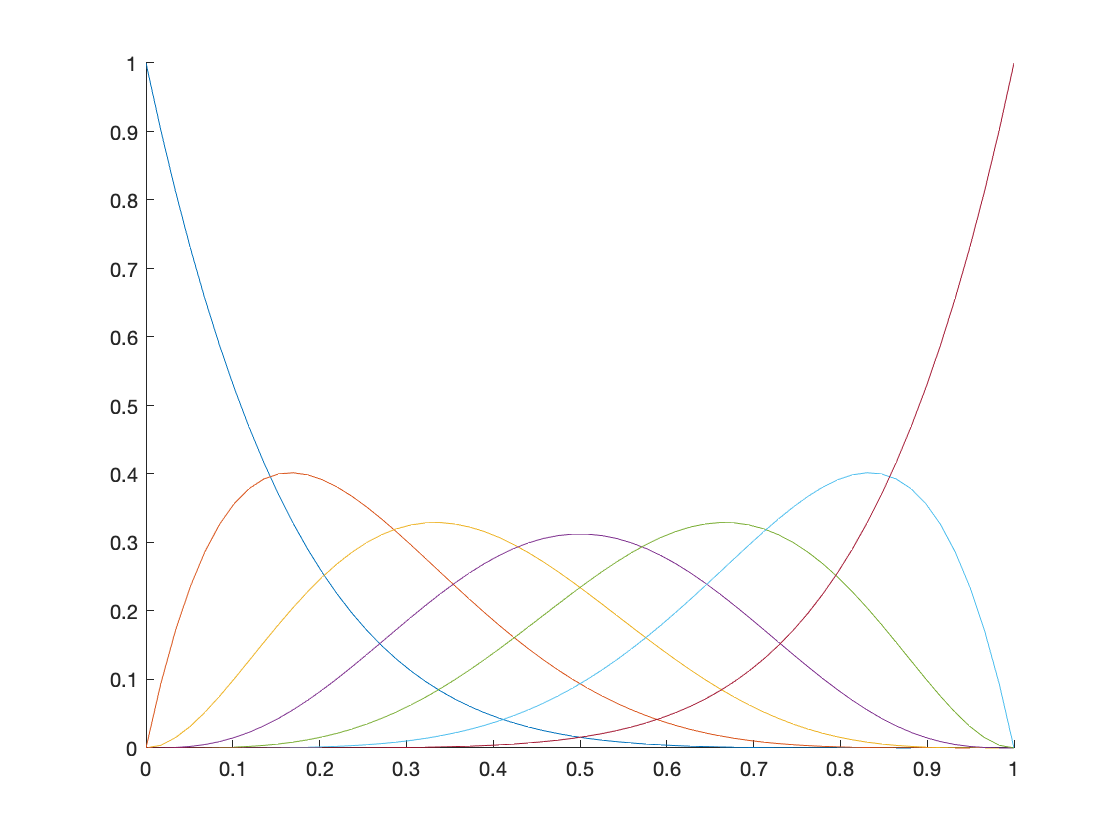

t=linspace(0,1,60); 
for j=0:6
    Bt(j+1,:)=nchoosek(6,j)*(1-t).^(6-j).*t.^j;
end
figure,hold on, for k=1:7; plot(t,Bt(k,:)), end

Tenemos dos variables: s, t. Consideramos una funcion de R^2 en R^2. Para s tenemos la matriz Bs, cada una de sus cinco filas es la evaluacion de un polinomio de Bernstein de grado cuatro.

Construimos 35=5x7 puntos en 2D, cinco en la direccion s y siete en la direcccion t. Esto genera un arreglo tridimensional 5x7x2

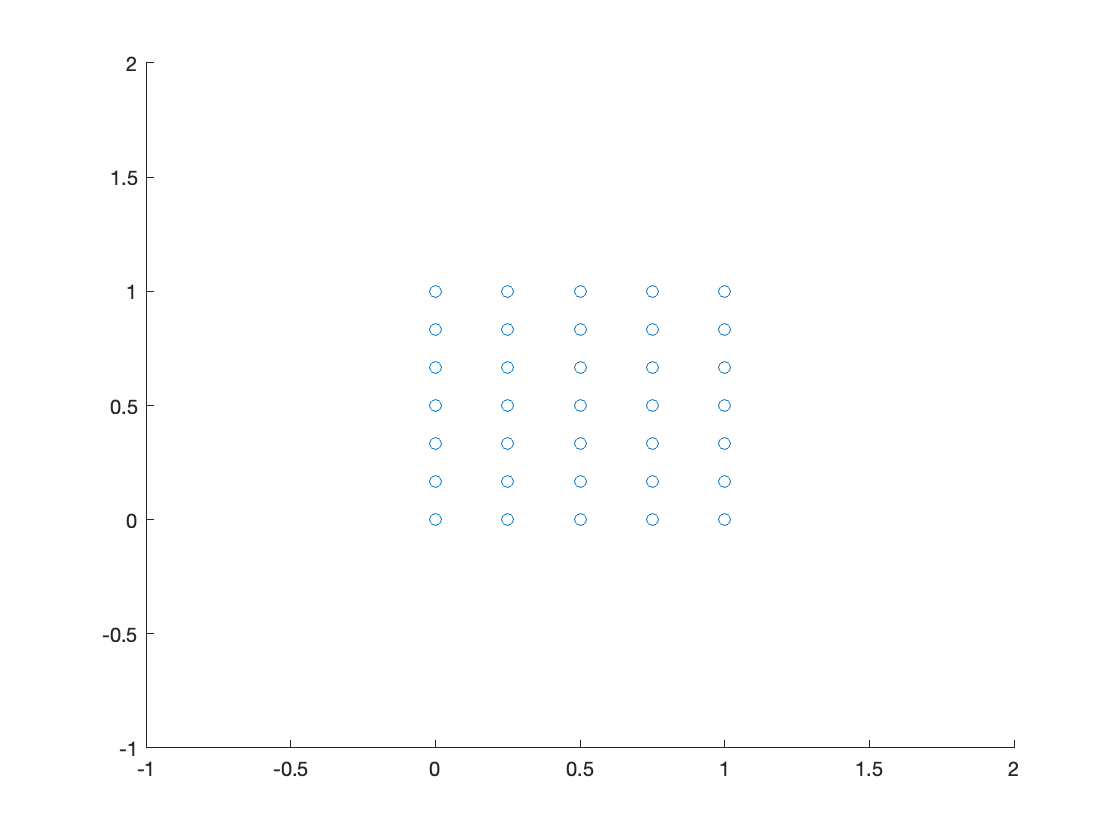

for i=1:5
    for j=1:7
        P(i,j,:)=[(i-1)/4,(j-1)/6];
    end
end
Q1=P(:,:,1); Q2=P(:,:,2);
Q11=Q1(:);Q22=Q2(:); 
figure, scatter(Q11,Q22); % despliega los 35 puntos
xlim([-1 2]), ylim([-1 2])

La funcion es la suma de los puntos dados por P, ponderada por los polinomios de Bernstein

x=transpose(Bt)*transpose(Q1)*Bs; % la 1era coordenada de la imagen
y=transpose(Bt)*transpose(Q2)*Bs; % la 2da coordenada de la imagen


La funcion que manda [s(j),t(i)] en [x(i,j),y(i,j)] es la identidad

% i=randi([1 50],1);j=randi([1 60],1); 
% [s(i),t(j)], [x(j,i),y(j,i)]


Ahora podemos llevar los puntos dados por P a 3D, le agregamos una 3era coordenada

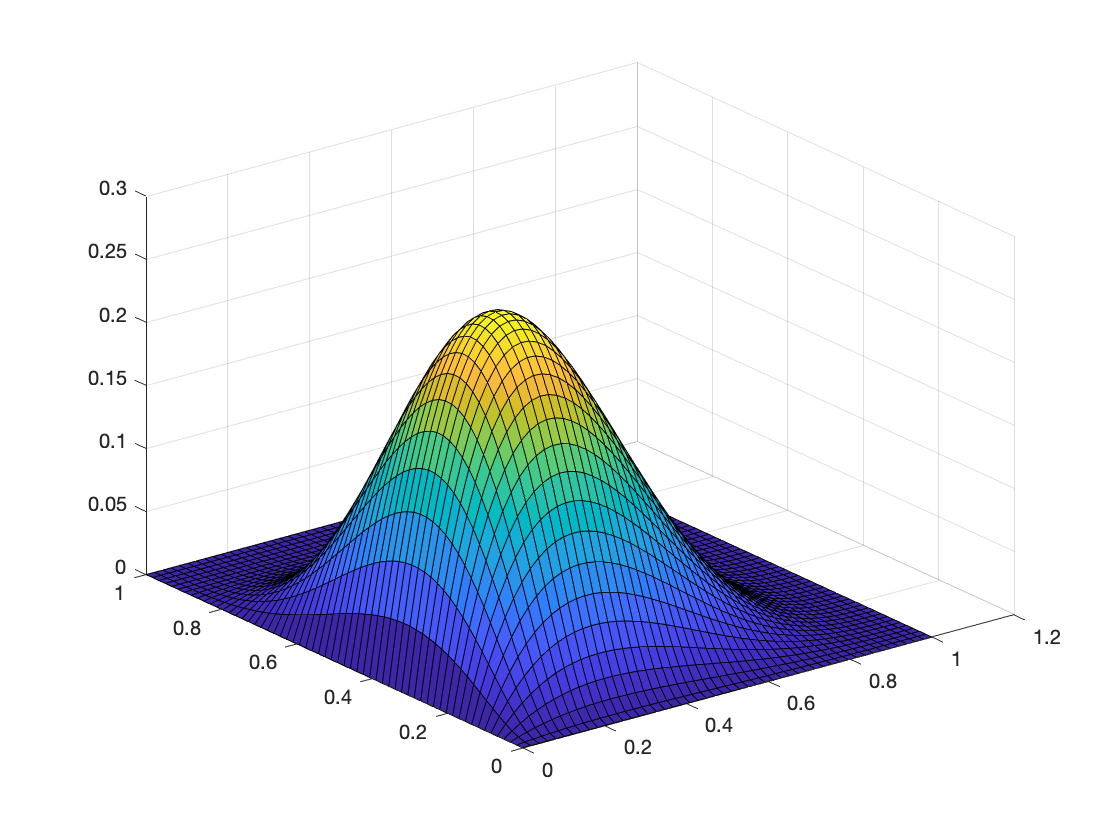

P(:,:,3)=0;
P(2,3,3)=2; % cambiamos un solo punto de control
Q3=P(:,:,3);

z=transpose(Bt)*transpose(Q3)*Bs; % la 3era coordenada de la imagen

figure, surf(x,y,z) % despliega rudimentariamente la superficie dada por Q1,Q2,Q3

B(s,t) = Bs_i * Bt_j * P_ij,  sumando sobre i y j y P_ij puntos en R^2. La funcion depende de lo P_ij. 

Pero si los escogemos adecuadamente la función B es la identidad: 

- s varía en [0,1], tomamos cinco puntos equidistanciados 0, 1/4, 1/2, 3/4 y 1.

- similarmente t, siete puntos equidist. 0, 1/6, 2/6, 3/6, 4/6, 5/6, 1

- y construimos 35 =5x7 ptos. de control: P_00=(0,0), P_01=(0,1/6), P_02=(0,2/6), .... , P_10=(1/4,0), P_11=(1/4,1/6), ... P(1/4,1) , ....  , P_55=(1,5/6), ... , P_56=(1,1)

- y resulta que la funcion B(s,t) es la identidad. 

**Ejercicio**: 

1) verifique con Matlab que B(s,t) coincide con (s,t)

2) demuestre teóricamente para todo (s,t) esta igualdad.

Ahora pasa algo interesantes: si desplaza uno de los P_ij, B(s,t) se puede hacer diferente de (s,t). 

Si movemos varios P_ij y aplicamos B(s,t) a [0,1]x[0,1], lo transformamos en otro objeto plano.

**Ejercicio**: Construya una tal transformacion en Matlab y dibuje el resultado de transformar  el cuadrado [0,1]x[0,1].

A veces el cambio de uno de los puntos de control P_ij no afecta a todos los (s,t). 

**Ejercicio**: determine que le pasa a un circulo contenido en el cuadrado [0,1]x[0,1] cuando deja invariantes todos los puntos de control del borde, pero desplaza algunos puntos internos. ¿Que pasa con los bordes? 

**Pregunta**: ¿que pasaría si se desplaza alguno de los P_ij del plano hacia 3D?